# Mapeo De Funciones

1) Se genera una matriz con los valores de la imagen original y la graficamos.

M=meshgrid(linspace(0,255,256),linspace(0,255,256));

figure
imagesc(M)
axis off
colormap gray

2) Definimos la Transformación.

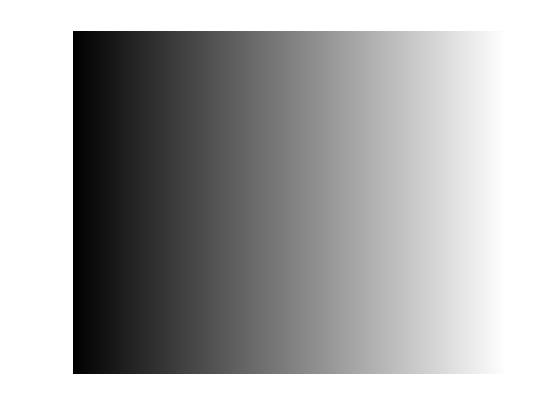

f = @(z) exp(z);

[sm,sn] = size(M);

[x,y] = meshgrid(linspace(pi,-pi,sm),linspace(-pi,pi,sn))

x =     3.1416    3.1170    3.0923    3.0677    3.0430    3.0184    2.9938    2.9691    2.9445    2.9198    2.8952    2.8706    2.8459    2.8213    2.7966    2.7720    2.7474    2.7227    2.6981    2.6734    2.6488    2.6242    2.5995    2.5749    2.5502    2.5256    2.5010    2.4763    2.4517    2.4270    2.4024    2.3778    2.3531    2.3285    2.3038    2.2792    2.2546    2.2299    2.2053    2.1806    2.1560    2.1314    2.1067    2.0821    2.0574    2.0328    2.0082    1.9835    1.9589    1.9342
    3.1416    3.1170    3.0923    3.0677    3.0430    3.0184    2.9938    2.9691    2.9445    2.9198    2.8952    2.8706    2.8459    2.8213    2.7966    2.7720    2.7474    2.7227    2.6981    2.6734    2.6488    2.6242    2.5995    2.5749    2.5502    2.5256    2.5010    2.4763    2.4517    2.4270    2.4024    2.3778    2.3531    2.3285    2.3038    2.2792    2.2546    2.2299    2.2053    2.1806    2.1560    2.1314    2.1067    2.0821    2.0574    2.0328    2.0082    1.9835    1.9589    1

y =    -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416   -3.1416
   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3.1170   -3


Z = x+y*1i

Z =    3.1416 - 3.1416i   3.1170 - 3.1416i   3.0923 - 3.1416i   3.0677 - 3.1416i   3.0430 - 3.1416i   3.0184 - 3.1416i   2.9938 - 3.1416i   2.9691 - 3.1416i   2.9445 - 3.1416i   2.9198 - 3.1416i   2.8952 - 3.1416i   2.8706 - 3.1416i   2.8459 - 3.1416i   2.8213 - 3.1416i   2.7966 - 3.1416i   2.7720 - 3.1416i   2.7474 - 3.1416i   2.7227 - 3.1416i   2.6981 - 3.1416i   2.6734 - 3.1416i   2.6488 - 3.1416i   2.6242 - 3.1416i   2.5995 - 3.1416i   2.5749 - 3.1416i   2.5502 - 3.1416i   2.5256 - 3.1416i   2.5010 - 3.1416i   2.4763 - 3.1416i   2.4517 - 3.1416i   2.4270 - 3.1416i   2.4024 - 3.1416i   2.3778 - 3.1416i   2.3531 - 3.1416i   2.3285 - 3.1416i   2.3038 - 3.1416i   2.2792 - 3.1416i   2.2546 - 3.1416i   2.2299 - 3.1416i   2.2053 - 3.1416i   2.1806 - 3.1416i   2.1560 - 3.1416i   2.1314 - 3.1416i   2.1067 - 3.1416i   2.0821 - 3.1416i   2.0574 - 3.1416i   2.0328 - 3.1416i   2.0082 - 3.1416i   1.9835 - 3.1416i   1.9589 - 3.1416i   1.9342 - 3.1416i
   3.1416 - 3.1170i   3.1170 - 3.1170i   3.09

f = @(z) exp(z);

Zt = f(Z);

re = real(Zt);
im = imag(Zt);

x = reshape(re,1,[]);
y = reshape(im,1,[]);
int = reshape(M,1,[]);

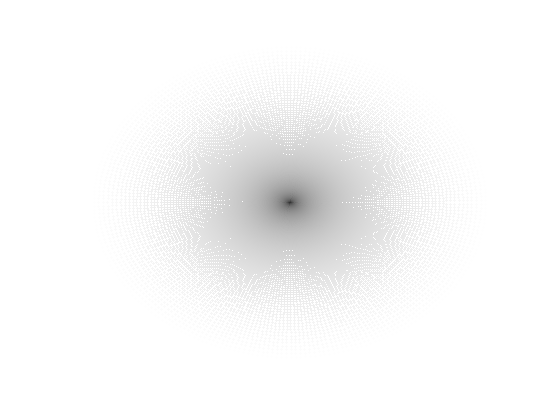

figure
scatter(x,y,5,int,'filled')
set(gca,'Color','g')
axis off
colormap gray